% Example comment this code =============
x = [2 3 5];
x = [1 3 5 7];
y = [5 7 8];
y = [24 120 336 720];
p = 2;
% Uncomment this code ==================
disp('Lagrange interpolation Method')

Lagrange interpolation Method


% x = input('Enter x values');
% y = input('Enter y values');
% p = input('Where to approximate');
x = x';
y = y';
table(x, y)

ans =     x     y 
    _    ___

    1     24
    3    120
    5    336
    7    720


n = length(x);
L = zeros(n, n);
% A = poly(3)
% B = poly(5)
% x = conv(A, B)*(5/-3)
% x = conv(A, B)
for i = 1: n
    v = 1;
    for j = 1: n
        if i~=j
            v = conv(v, poly(x(j)))/(x(i)-x(j));
        end
    end
    L(i, : ) = v*y(i);
end
L

L =    -0.5000    7.5000  -35.5000   52.5000
    7.5000  -97.5000  352.5000 -262.5000
  -21.0000  231.0000 -651.0000  441.0000
   15.0000 -135.0000  345.0000 -225.0000


equation = sum(L)

equation =      1     6    11     6


result = polyval(equation , p);
fprintf('Approximatio value for %d is %d', p, result);

Approximatio value for 2 is 60

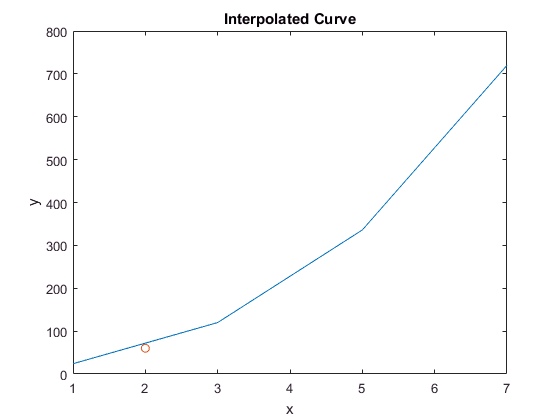

plot(x, y)
hold on;
plot(p, result,'o')
xlabel('x');
ylabel('y');
title('Interpolated Curve')
hold off